# [使用 gRPC API 以编程方式控制 RoadRunner](https://ww2.mathworks.cn/help/releases/R2022b/roadrunner/ug/control-roadrunner-programmatically-using-grpc-api.html)

`RoadRunner` 提供了一个 API，使您能够以编程方式控制 `RoadRunner` 用户界面。例如，使用此 API，您可以：

- 创建、加载和保存 `RoadRunner` 场景、场景和项目。

- 将 ASAM OpenDRIVE 文件导入场景。

- 将场景和情景导出为 RoadRunner 支持的一种文件格式。

RoadRunner 使您能够以各种编程语言编译 API 版本，并以您选择的语言调用它们。或者，您可以使用 API 的预编译版本，使您能够从命令行控制 RoadRunner 。

## **RoadRunner** **API 的工作****原理**

RoadRunner API 是使用 [gRPC](https://github.com/grpc/grpc/) 框架构建的。该框架使用客户端-服务器架构，其中客户端应用程序使用一组远程过程调用方法远程控制服务器应用程序。在 RoadRunner 中：

- 本地安装的 RoadRunner 版本是服务器应用程序。

- RoadRunner API 提供了用于远程控制 RoadRunner 的远程过程调用方法。

- 为调用远程过程调用方法而编写的程序是客户端应用程序。gRPC 框架是语言中立的和平台中立的。可以使用gRPC支持的任何平台和语言编写调用RoadRunner API 的客户端。有关 gRPC 支持的语言和平台的详细信息，请参阅[gRPC文档](https://grpc.io/docs/)。

此图显示了 API 架构的简化布局。在此图中，Python 客户端使用在 RoadRunner 中的 [`LoadScene`](https://ww2.mathworks.cn/help/roadrunner/ref/loadscene.html) 方法中加载场景。

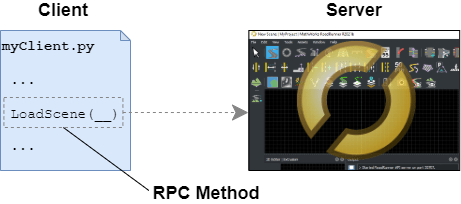

**RoadRunner ****API如何****发送和接收数据**

RoadRunner API 的 RPC 方法在 gRPC 服务中定义 。每次调用属于 gRPC 服务的方法时，该方法：

- 向服务器发送请求。

- 从服务器接收返回的响应。

此图显示了 `LoadScene` 方法调用的请求-响应格式。在客户端中，方法 `LoadSceneRequest` 的输入是客户端向 `RoadRunner` 应用程序服务器发送的请求。`RoadRunner` 处理此请求，加载场景，并发回响应 `LoadSceneResponse`。

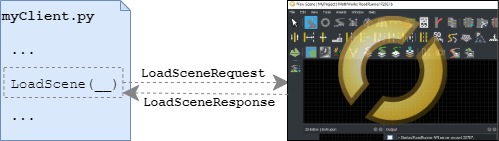

这些请求和响应中的数据被构造为 protobuf 模式定义的消息。protobuf 模式是由谷歌开发的一种语言中立格式，并针对快速高效的数据传输进行了优化。RoadRunner 服务器可以同时发送和接收来自这些 API 调用的数百万条 protobuf 消息，同时保持 RoadRunner 的实时更新。

protobuf 模式中的消息在具有扩展名`.proto`的文本文件中定义。这些消息包含定义：

- 可以在消息中指定的字段名称。

- 字段的数据类型。例如，可以将字段指定为布尔值、字符串或其他 protobuf 消息。

考虑 LoadScene RPC 方法的模式，如[` roadrunner_service.proto`](https://ww2.mathworks.cn/help/roadrunner/ref/roadrunner_service.proto.html) 文件中所定义的。

        `// 加载场景`

        `rpc LoadScene (LoadSceneRequest) returns (LoadSceneResponse) {}`

请求消息 `LoadSceneRequest` 和响应消息 `LoadScineResponse` 的模式在 [`roadrunner_service_messages.proto`](https://ww2.mathworks.cn/help/roadrunner/ref/roadrunner_service_messages.proto.html) 文件中定义。`LoadSceneRequest` 接受一个必需的输入 `file_path` ，这是一个指定要加载的文件路径的字符串。

        `message LoadSceneRequest`

        `{`

        `  // Scene file to load (required)`

        `  string file_path = 1;`

        `}`

`RoadRunner` 处理请求（尝试加载场景）后， `RoadRunner` API 服务器发回一条空 `LoadSceneResponse` 消息作为响应。

        `message LoadSceneResponse`

        `{`

        `}`

由于 protobuf 架构与语言无关，因此用于调用方法和格式化消息请求的语法取决于您用于编写客户端应用程序的编程语言。

## **连接到 RoadRunner ****API 服务器**

要使用 `RoadRunner` API，您必须先与 `RoadRunner `API 服务器建立网络连接。此服务器是本地RoadRunner安装的一部分，并在您打开项目时开始运行。

要以编程方式打开 `RoadRunner` 并启动 API 服务器，从本地RoadRunner安装调用可执行文件 [`AppRoadRunner`](https://ww2.mathworks.cn/help/roadrunner/ref/approadrunner.html)。此可执行文件包含使您能够指定的命令行选项：

- `RoadRunner` 打开的项目

- `RoadRunner` API 服务器运行的 IP 网口

此命令行代码显示如何从其在Windows®上的默认安装位置打开RoadRunner。RoadRunner打开一个位于 `C:\RR\MyProject `端口为 54321 的项目。

cd("C:\Program Files\RoadRunner R2022b\bin\win64")
!AppRoadRunner --projectPath C:\RR\MyProject --apiPort 54321

RoadRunner的**输出**面板显示了 RoadRunner API 服务器运行的端口。

## **从命令行使用 RoadRunner API**

`RoadRunner` 提供了一个预编译的帮助程序命令 `CmdRoadRunnerApi`，能够从命令行调用 `RoadRunner` RPC 方法。此帮助程序命令与 `AppRoadRunner `可执行文件位于同一文件夹中 。

此代码调用 `LoadScene `方法从打开的项目加载预建 `FourWaySignal` 场景。

cd("C:\Program Files\RoadRunner R2022b\bin\win64")
!CmdRoadRunnerApi "LoadScene(file_path='FourWaySignal')" --serverAddress=localhost:54321

## **在各种编程语言中使用 RoadRunner API**

为了更加灵活地使用 RoadRunner API，您可以将 API 编译成 gRPC 支持的语言，然后使用该语言编写客户端应用程序以编程方式控制 RoadRunner。

### **编译 RoadRunner** **API**

要用所需的编程语言编译 RoadRunner API，必须首先将定义 API 的 protobuf 文件复制到一个可写文件夹中。这些文件位于本地 RoadRunner 安装中。然后，可以使用 protobuf 编译器以及所需编程语言的 gRPC 插件来编译 RoadRunner API 的特定语言版本或绑定。例如，此图显示了 Python 和 C++ 绑定的生成。

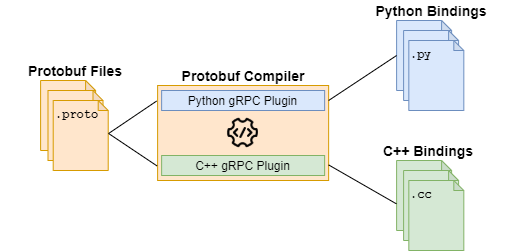

有关编译 protobuf 文件的详细信息，请参考[为 RoadRunner gRPC API 编译 protobuf](https://ww2.mathworks.cn/help/roadrunner/ug/compile-protocol-buffers-for-roadrunner-grpc-api.html)。

### **创建 RoadRunner** **API 客户端**

您编写的以编程方式控制 RoadRunner 的客户端通常包含执行以下步骤的代码：

- 从已编译的绑定中导入 gRPC 代码。

- 与 RoadRunner API 服务器建立本地网络连接。

- 使用导入的 gRPC 代码创建 RoadRunner API 对象。该对象称为 *存根*。

- 从此存根调用 RPC 方法以通过本地网络控制 RoadRunner 。

这个简单的 Python 客户端显示了调用该 `LoadScene `方法的示例 。

        `import grpc`

        `from mathworks.roadrunner import roadrunner_service_messages_pb2`

        `from mathworks.roadrunner import roadrunner_service_pb2_grpc`

        `with grpc.insecure_channel("localhost:54321") as channel:`

                `api = roadrunner_service_pb2_grpc.RoadRunnerServiceStub(channel)`

                `loadSceneRequest = roadrunner_service_messages_pb2.LoadSceneRequest()`

                `loadSceneRequest.file_path = "FourWaySignal"`

                `api.LoadScene(loadSceneRequest)`

导入已编译的 gRPC Python 绑定后，此客户端通过 gRPC 通道建立连接并为 RoadRunner 服务 API 创建存根。API 的 gRPC 通道使用不安全的通道凭据，并且没有加密或身份验证。由于 RoadRunner 通常在本地计算机上运行并且不连接到外部网络，因此安全风险很低。然后，客户端 `LoadScene`从 API 存根调用， `FourWaySignal `从当前打开的项目加载预构建场景。

您可以让多个客户端同时调用 RPC 方法，只要它们连接到同一网络端口上的 RoadRunner 。例如，在此图中，Python 客户端和 C++ 客户端都通过网络端口 `54321 `进行调用 `LoadScene`。